# **Lab 7**

#### Task 1:

Part (a)

% Define the first set of signals
x = [0.5 2];
h = [1 1 1];

m = length(x);
o = length(h);
k = m + o - 1;

% Initialize y_manual and y_conv as arrays of zeros
y_manual = zeros(1, k);

% Perform convolution manually using nested loops
for i = 1:k
    for j = 1:m
        if i - j + 1 > 0 && i - j + 1 <= o
            y_manual(i) = y_manual(i) + x(j) * h(i - j + 1);
        end
    end
end

y_manual

y_manual =     0.5000    2.5000    2.5000    2.0000


% Perform convolution using the built-in 'conv' function
y_conv = conv(x, h)

y_conv =     0.5000    2.5000    2.5000    2.0000


% Compare the results
isequal(y_manual, y_conv) % Check if the results are equal

ans = logical
   1


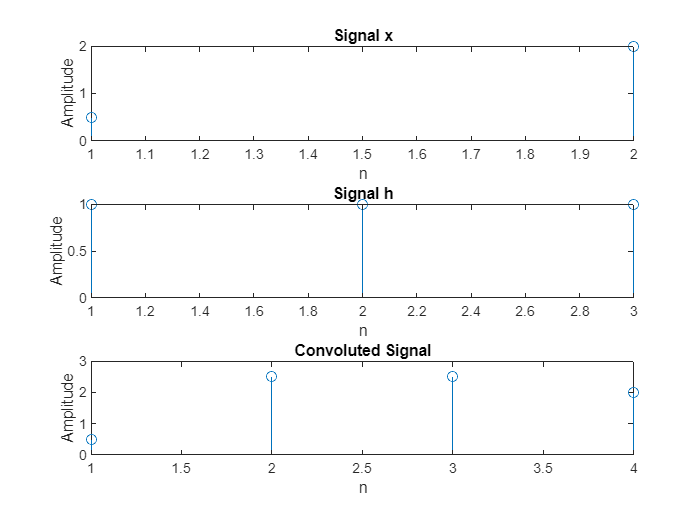

n = 1:m;

figure;

% Plot the signals and their convolution result
subplot(3, 1, 1);
stem(n, x);
title('Signal x');
xlabel('n');
ylabel('Amplitude');

n = 1:o;

subplot(3, 1, 2);
stem(n, h);
title('Signal h');
xlabel('n');
ylabel('Amplitude');

z =  1: k;

subplot(3, 1, 3);
stem(z, y_conv);
title('Convoluted Signal');
xlabel('n');
ylabel('Amplitude');

Part (b)

% Define the second set of signals
n2 = 0:4;
x = ones(1, length(n2))

x =      1     1     1     1     1


n3 = 0:6;
a = 0.5; % You can change the value of 'a' as needed
h = a.^n3

h =     1.0000    0.5000    0.2500    0.1250    0.0625    0.0312    0.0156


m = length(x);
o = length(h);
k = m + o - 1;

% Initialize y_manual and y_conv as arrays of zeros
y_manual = zeros(1, k);

% Perform convolution manually using nested loops
for i = 1:k
    for j = 1:m
        if i - j + 1 > 0 && i - j + 1 <= o
            y_manual(i) = y_manual(i) + x(j) * h(i - j + 1);
        end
    end
end

y_manual

y_manual =     1.0000    1.5000    1.7500    1.8750    1.9375    0.9688    0.4844    0.2344    0.1094    0.0469    0.0156


% Perform convolution using the built-in 'conv' function
y_conv = conv(x, h)

y_conv =     1.0000    1.5000    1.7500    1.8750    1.9375    0.9688    0.4844    0.2344    0.1094    0.0469    0.0156


% Compare the results
isequal(y_manual, y_conv) % Check if the results are equal

ans = logical
   1


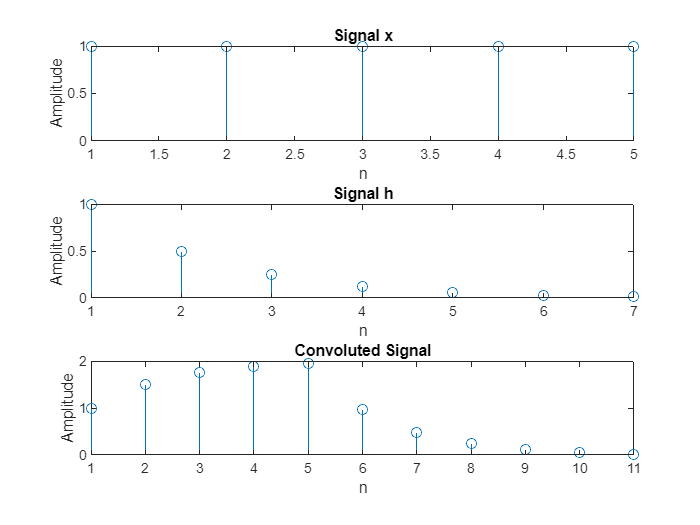

n = 1:m;

% Plot the signals and their convolution result
subplot(3, 1, 1);
stem(n, x);
title('Signal x');
xlabel('n');
ylabel('Amplitude');

n = 1:o;

subplot(3, 1, 2);
stem(n, h);
title('Signal h');
xlabel('n');
ylabel('Amplitude');

z =  1: k;

subplot(3, 1, 3);
stem(z, y_conv);
title('Convoluted Signal');
xlabel('n');
ylabel('Amplitude');

#### Task 2:

% Set the duration of the recording in seconds
duration = 5; % 5 seconds

% Create an audiorecorder object
recObj = audiorecorder(44100, 16, 1); % Sampling rate: 44.1 kHz, 16-bit, mono

% Record the audio for the specified duration
disp('Recording...');

Recording...


recordblocking(recObj, duration);
disp('Recording Finished.');

Recording Finished.


% Save the recorded audio as a .wav file
audiowrite('My_Recording.wav', getaudiodata(recObj), recObj.SampleRate);

% Read the .wav file
[y, fs] = audioread('My_Recording.wav');
% Play the sound file in different ways

% Play the complete file
sound(y, fs);
pause(duration); % Wait for the sound to finish

% Play the first half and second half of the file separately
half_duration = duration / 2;
sound(y(1:round(half_duration * fs)), fs);
pause(half_duration); % Wait for the first half to finish
sound(y(round(half_duration * fs) + 1:end), fs);
pause(half_duration); % Wait for the second half to finish

% Play the middle one-third of the file
third_duration = duration / 3;
start_index = round((duration - third_duration) / 2 * fs);
end_index = start_index + round(third_duration * fs);
sound(y(start_index:end_index), fs);

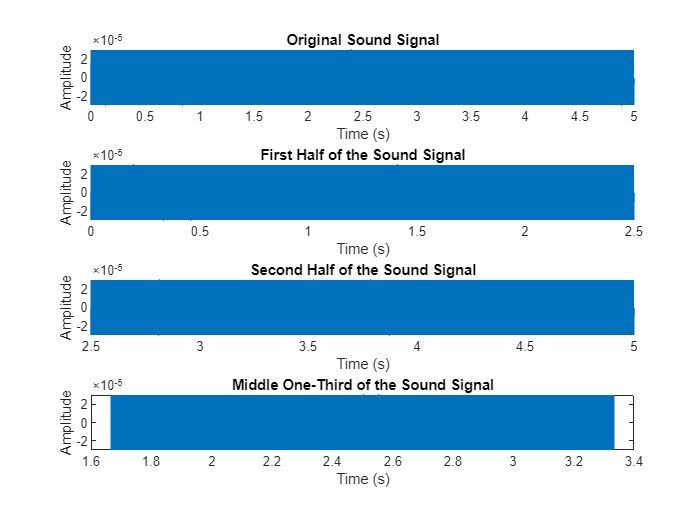

% Plot the original sound signal
figure;
subplot(4,1,1);
plot((1:length(y)) / fs, y);
title('Original Sound Signal');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot the first half and second half of the file separately
half_duration = duration / 2;
subplot(4,1,2);
plot((1:round(half_duration * fs)) / fs, y(1:round(half_duration * fs)));
title('First Half of the Sound Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,3);
plot((round(half_duration * fs) + 1:length(y)) / fs, y(round(half_duration * fs) + 1:end));
title('Second Half of the Sound Signal');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot the middle one-third of the file
third_duration = duration / 3;
start_index = round((duration - third_duration) / 2 * fs);
end_index = start_index + round(third_duration * fs);

subplot(4,1,4);
plot((start_index:end_index) / fs, y(start_index:end_index));
title('Middle One-Third of the Sound Signal');
xlabel('Time (s)');
ylabel('Amplitude');